**resources to read : **

- [https://in.mathworks.com/help/vision/ref/vision.pointtracker-system-object.html](https://in.mathworks.com/help/vision/ref/vision.pointtracker-system-object.html) 

- [https://in.mathworks.com/help/vision/ref/vision.cascadeobjectdetector-system-object.html#bs_kj0p](https://in.mathworks.com/help/vision/ref/vision.cascadeobjectdetector-system-object.html#bs_kj0p) 

- [https://in.mathworks.com/help/vision/examples/face-detection-and-tracking-using-the-klt-algorithm.html](https://in.mathworks.com/help/vision/examples/face-detection-and-tracking-using-the-klt-algorithm.html) 

- [https://in.mathworks.com/matlabcentral/fileexchange/68985-real-time-facial-recognition-using-hog-features](https://in.mathworks.com/matlabcentral/fileexchange/68985-real-time-facial-recognition-using-hog-features) 

- **ready your system with cam , model to take images**

1.1 clear all ,the system

clc
clear all
close all

1.2 ** start and set your system **

%webcamlist
%preview(cam)
% Create the face detector object.This is the default-> FrontalFaceCART
faceDetector = vision.CascadeObjectDetector();
% Create the point tracker object.
pointTracker = vision.PointTracker('MaxBidirectionalError', 2);
% Capture one frame to get its size.
cam = webcam;
videoFrame = snapshot(cam)

videoFrame = 480×640×3 uint8 array
videoFrame(:,:,1) =

    8    8    2    2    0    0    0    0    0    0    0    0    0    0    0    0    0    0    3    3    6    6    6    6    6    6    6    6    6    6    6    6    8    8    8    8    8    8    6    6    3    3    3    3    3    3    2    2    2    2    0    0    0    0    0    0    0    0    0    0    2    2    2    2    0    0    0    0    0    0    2    2    2    2    0    0    0    0    0    0    0    0    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    2    2    2    2    2    2    2    2    2    2    3    3    3    3    3    3    3    3    3    3    3    3    5    5    5    5    5    5    5    5    5    5    5    5    5    5    

frameSize = size(videoFrame)

frameSize =    480   640     3


% Create the video player object.
videoPlayer = vision.VideoPlayer('Position', [100 100 [frameSize(2), frameSize(1)]+30])

videoPlayer =   vision.VideoPlayer with properties:

        Name: 'Video Player'
    Position: [100 100 670 510]


**2. create the database.**

cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
    BacklightCompensation: 0
                 Exposure: -6
         WhiteBalanceMode: 'auto'
             ExposureMode: 'auto'
               Saturation: 50
                      Hue: 0
                    Gamma: 300
             WhiteBalance: 4600
                Sharpness: 50
               Brightness: 0
                 Contrast: 50


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
               Brightness: 0
             WhiteBalance: 4600
                    Gamma: 300
                 Exposure: -6
                      Hue: 0
             ExposureMode: 'auto'
               Saturation: 50
                 Contrast: 50
    BacklightCompensation: 0
         WhiteBalanceMode: 'auto'
                Sharpness: 50


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
             WhiteBalance: 4600
             ExposureMode: 'auto'
         WhiteBalanceMode: 'auto'
               Saturation: 50
               Brightness: 0
                Sharpness: 50
                 Exposure: -6
                    Gamma: 300
                      Hue: 0
                 Contrast: 50
    BacklightCompensation: 0


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
             WhiteBalance: 4600
                 Exposure: -6
               Saturation: 50
    BacklightCompensation: 0
                Sharpness: 50
                      Hue: 0
                 Contrast: 50
               Brightness: 0
             ExposureMode: 'auto'
         WhiteBalanceMode: 'auto'
                    Gamma: 300


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
             WhiteBalance: 4600
                 Exposure: -6
                 Contrast: 50
                Sharpness: 50
                    Gamma: 300
             ExposureMode: 'auto'
               Brightness: 0
    BacklightCompensation: 0
                      Hue: 0
               Saturation: 50
         WhiteBalanceMode: 'auto'


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
             ExposureMode: 'auto'
                 Contrast: 50
         WhiteBalanceMode: 'auto'
                 Exposure: -6
                Sharpness: 50
    BacklightCompensation: 0
               Saturation: 50
                      Hue: 0
                    Gamma: 300
             WhiteBalance: 4600
               Brightness: 0


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
                 Exposure: -6
                    Gamma: 300
                      Hue: 0
             WhiteBalance: 4600
               Saturation: 50
             ExposureMode: 'auto'
               Brightness: 0
    BacklightCompensation: 0
         WhiteBalanceMode: 'auto'
                Sharpness: 50
                 Contrast: 50


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
             WhiteBalance: 4600
                Sharpness: 50
               Saturation: 50
         WhiteBalanceMode: 'auto'
                    Gamma: 300
             ExposureMode: 'auto'
    BacklightCompensation: 0
                 Exposure: -6
                      Hue: 0
                 Contrast: 50
               Brightness: 0


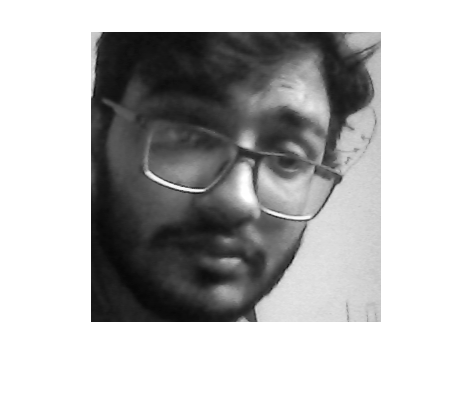

cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
    BacklightCompensation: 0
                      Hue: 0
               Saturation: 50
         WhiteBalanceMode: 'auto'
             WhiteBalance: 4600
                Sharpness: 50
                    Gamma: 300
                 Exposure: -6
                 Contrast: 50
             ExposureMode: 'auto'
               Brightness: 0


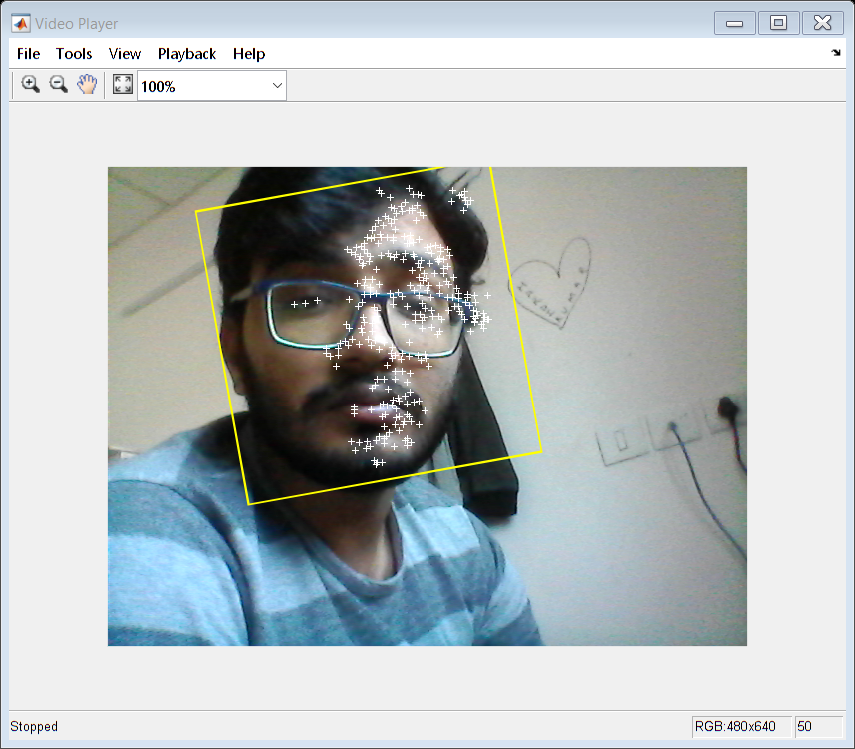

Index in position 1 is invalid. Array indices must be positive integers or logical values.

for j = 52:62
    cam = webcam
    runLoop = true;
    numPts = 0;
    frameCount = 0;
    while runLoop && frameCount < 50
         % Get the next frame.
        videoFrame = snapshot(cam);
        
        % Get frame to save data to database
        videoFrameGray = rgb2gray(videoFrame);
        frameCount = frameCount + 1;
        
        if numPts < 100
            % Detection mode.
            bbox = faceDetector.step(videoFrameGray);
            if ~isempty(bbox)
                % Find corner points inside the detected region.
                points = detectMinEigenFeatures(videoFrameGray, 'ROI', bbox(1, :));
                
                % Re-initialize the point tracker.
                xyPoints = points.Location;
                numPts = size(xyPoints,1);
                release(pointTracker);
                initialize(pointTracker, xyPoints, videoFrameGray);
                
                % Save a copy of the points.
                oldPoints = xyPoints;
                
                % Convert the rectangle represented as [x, y, w, h] into an
                % M-by-2 matrix of [x,y] coordinates of the four corners. This
                % is needed to be able to transform the bounding box to display
                % the orientation of the face.
                bboxPoints = bbox2points(bbox(1, :));
                
                % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
                % format required by insertShape.
                bboxPolygon = reshape(bboxPoints', 1, []);
                
                % Display a bounding box around the detected face.
                videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);
                
                % Display detected corners.
                videoFrame = insertMarker(videoFrame, xyPoints, '+', 'Color', 'blue');
            end
            
      else
            % Tracking mode.
            [xyPoints, isFound] = step(pointTracker, videoFrameGray);
            visiblePoints = xyPoints(isFound, :);
            oldInliers = oldPoints(isFound, :);
            numPts = size(visiblePoints, 1);
            if numPts >= 100
                % Estimate the geometric transformation between the old points
                % and the new points.
                [xform, oldInliers, visiblePoints] = estimateGeometricTransform(...
                    oldInliers, visiblePoints, 'similarity', 'MaxDistance', 4);
                % Apply the transformation to the bounding box.
                bboxPoints = transformPointsForward(xform, bboxPoints);
                % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
                % format required by insertShape.
                bboxPolygon = reshape(bboxPoints', 1, []);
                
                % Display a bounding box around the face being tracked.
                videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);
                % Display tracked points.
                videoFrame = insertMarker(videoFrame, visiblePoints, '+', 'Color', 'white');
                % Reset the points.
                oldPoints = visiblePoints;
                setPoints(pointTracker, oldPoints);
            end
        end
        
          % Display the annotated video frame using the video player object.
        step(videoPlayer, videoFrame);
        % Check whether the video player window has been closed.
        runLoop = isOpen(videoPlayer);
    end
    % Clean up.
    clear cam;
    release(videoPlayer);
    release(pointTracker);
    release(faceDetector);
    
    % saving the image to database
    position1 = min(bboxPolygon(2),bboxPolygon(4));
    position2 = max(bboxPolygon(6),bboxPolygon(8));
    position3 = min(bboxPolygon(1),bboxPolygon(7));
    position4 = max(bboxPolygon(3),bboxPolygon(5));
    warning('off')
    getimage = videoFrameGray(position1:position2,position3:position4,:);
    imshow(getimage)
    %resize image
    getimage = imresize(getimage, [300 300]);
    % Modify here. In the folder database2, label the name of ppl and put their
    % faces inside the folder.
    sprintf('image%d', j);
    imwrite(getimage,strcat('Rohit',num2str(j),'.jpg'),'jpg');
    pause(1)
end 


**3. train your model **

**3.1 - let's visualise first how HOG features look like.**

%% Load Image Information from ATT Face Database Directory
faceDatabase = imageSet('database','recursive');
%% Split Database into Training & Test Sets
training = faceDatabase

training =   imageSet with properties:

      Description: 'Rohit'
    ImageLocation: {1×47 cell}
            Count: 47


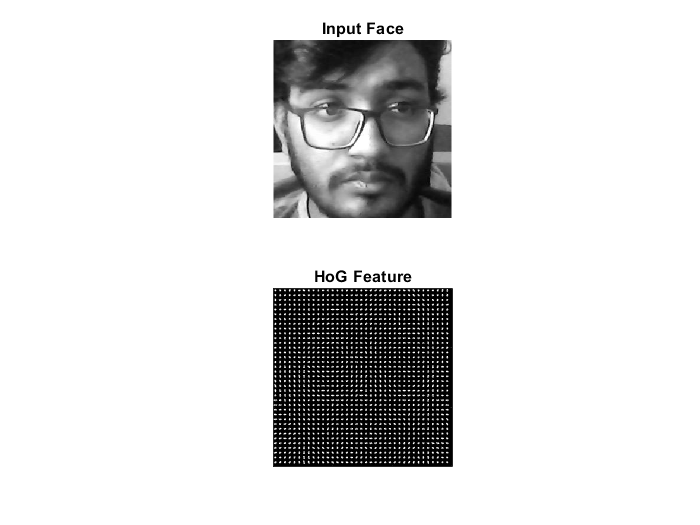

%% Extract and display Histogram of Oriented Gradient Features for single face 
person = 1;
[hogFeature, visualization]= extractHOGFeatures(read(training(person),1));
figure;
subplot(2,1,1); imshow(read(training(person),1)); title('Input Face');
subplot(2,1,2); plot(visualization); title('HoG Feature');

**3.2 - let's extract the whole features of my training set.**

%create an array of size equal to the size of whole dataset
trainingFeatures = zeros(size(training,2)*training(1).Count,46656);
featureCount = 1;
for i=1:size(training,2)
    for j = 1:training(i).Count
        points = detectSURFFeatures(read(training(i),j)); % points
        trainingFeatures(featureCount,:) = extractHOGFeatures(read(training(i),j));% reading the image & HOG
        trainingLabel{featureCount} = training(i).Description;    
        featureCount = featureCount + 1;
    end
    personIndex{i} = training(i).Description;
end
% Create 40 class classifier using  
faceClassifier = fitcecoc(trainingFeatures,trainingLabel);

cam = webcam;

**4. Run video for prediction **

runLoop = true;
numPts = 0;
frameCount = 0;
%cam = webcam('Integrated Camera');
while runLoop && frameCount >=0
    % Get the next frame.
   
    videoFrame = snapshot(cam);
    
    % Get frame to save data to database
    videoFrame2 = snapshot(cam);
    videoFrameGray = rgb2gray(videoFrame);
    frameCount = frameCount + 1;
    if numPts < 20
        % Detection mode.
        bbox = faceDetector.step(videoFrameGray);
        if ~isempty(bbox)
            % Find corner points inside the detected region.
            points = detectMinEigenFeatures(videoFrameGray, 'ROI', bbox(1, :));
            % Re-initialize the point tracker.
            xyPoints = points.Location;
            numPts = size(xyPoints,1);
            release(pointTracker);
            initialize(pointTracker, xyPoints, videoFrameGray);
            % Save a copy of the points.
            oldPoints = xyPoints;
            % Convert the rectangle represented as [x, y, w, h] into an
            % M-by-2 matrix of [x,y] coordinates of the four corners. This
            % is needed to be able to transform the bounding box to display
            % the orientation of the face.
            bboxPoints = bbox2points(bbox(1, :));
            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);
            % Display a bounding box around the detected face.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);
            % Display detected corners.
            videoFrame = insertMarker(videoFrame, xyPoints, '+', 'Color', 'white');
        end
    else
        % Tracking mode.
        [xyPoints, isFound] = step(pointTracker, videoFrameGray);
        visiblePoints = xyPoints(isFound, :);
        oldInliers = oldPoints(isFound, :);
        numPts = size(visiblePoints, 1);
        if numPts >=20
            
            % Estimate the geometric transformation between the old points
            % and the new points.
            [xform, oldInliers, visiblePoints] = estimateGeometricTransform(...
                oldInliers, visiblePoints, 'similarity', 'MaxDistance', 4);
            % Apply the transformation to the bounding box.
            bboxPoints = transformPointsForward(xform, bboxPoints);
            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);
            
            % Display a bounding box around the face being tracked.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);
            % Display tracked points.
            videoFrame = insertMarker(videoFrame, visiblePoints, '+', 'Color', 'white');
            % Reset the points.
            oldPoints = visiblePoints;
            setPoints(pointTracker, oldPoints);
            
            position1 = min(bboxPolygon(2),bboxPolygon(4));
            position2 = max(bboxPolygon(6),bboxPolygon(8));
            position3 = min(bboxPolygon(1),bboxPolygon(7));
            position4 = max(bboxPolygon(3),bboxPolygon(5));
            
            warning('off')
            if position2<480 && position4<480 && position1>0 && position3>0
            getimage = videoFrameGray(position1:position2,position3:position4,:);
            %resize image
            getimage = imresize(getimage, [300 300]);
            
            queryFeatures = extractHOGFeatures(getimage);
            [personLabel,PostProbs]  = predict(faceClassifier,queryFeatures);
            %maxpro = max(abs(PostProbs(1)),abs(PostProbs(2)));
            maxpro = max(abs(PostProbs(1)));
            position = [position3 position2];
            box_color = {'yellow'};
            string = strcat(personLabel,num2str(maxpro));
            videoFrame = insertText(videoFrame,position,string,'FontSize',18,'BoxColor',...
            box_color,'BoxOpacity',0.4,'TextColor','white');
            end
        end
    end
    % Display the annotated video frame using the video player object.
    step(videoPlayer, videoFrame);
    % Check whether the video player window has been closed.
    runLoop = isOpen(videoPlayer);
end
% Clean up.
clear cam;
release(videoPlayer);
